load('heparosan_GP.mat')
load('results_cL1_10_cL2_10_cU1_20_cU2_20_date_20240331_154057.mat')
% Given hexadecimal color codes
hex_colors = {'#66156b', '#802575', '#98377e', '#af4a86', '#c45e8e', ...
    '#d77495', '#e78c9a', '#f4a59e', '#fcc0a1', '#ffdda1'};

% Initialize an empty array to store RGB values
rgb_values = zeros(numel(hex_colors), 3);

% Convert hexadecimal color codes to RGB decimal values
for i = 1:numel(hex_colors)
    hex = hex_colors{i}(2:end); % Remove the '#' character
    rgb_values(i, :) = sscanf(hex, '%2x%2x%2x') / 255; % Convert hex to RGB and normalize
end

 % Define the number of samples
num_samples = 10;  % Adjust as needed

% Define the limits for both dimensions
lower_limit = 0;
upper_limit = 7.5;

% Generate Latin hypercube samples
lhs_samples = lhsdesign(num_samples, 2, 'criterion', 'maximin', 'iterations', 100);

% Scale the samples to fit within the limits
lhs_samples = lhs_samples * (upper_limit - lower_limit) + lower_limit;

GlcNAc_I = lhs_samples(:,1)

GlcNAc_I =     0.9785
    5.2793
    6.3403
    4.7726
    1.8218
    3.0547
    0.1022
    7.3726
    4.3660
    2.8174


GlcUA_I = lhs_samples(:,2)

GlcUA_I =     3.9362
    0.6006
    5.2628
    4.7178
    6.6184
    0.8563
    1.5679
    6.7788
    2.5721
    3.3278


[Mw_pred,Mw_sd,Mw_int] = predict(gprMdl_Mw, [GlcNAc_I(:), GlcUA_I(:)])

Mw_pred =    70.1873
   24.8550
   69.2236
   61.3097
   51.0204
   68.1848
  117.3514
   81.4461
   47.5718
   64.0389


Mw_sd =     2.9387
    2.2711
    3.7017
    2.1738
    4.6355
    3.3696
    2.8988
    6.5362
    3.4508
    3.9661


Mw_int =    64.4275   75.9472
   20.4037   29.3062
   61.9685   76.4787
   57.0492   65.5702
   41.9350   60.1057
   61.5805   74.7891
  111.6699  123.0330
   68.6353   94.2569
   40.8084   54.3352
   56.2655   71.8123


[PDI_pred,~,PDI_int] = predict(gprMdl_pdi, [GlcNAc_I(:), GlcUA_I(:)])

PDI_pred =     1.2886
    1.2828
    1.6121
    1.6123
    1.3571
    1.2801
    1.1877
    1.5189
    1.4677
    1.4372


PDI_int =     1.2383    1.3388
    1.2503    1.3153
    1.5468    1.6775
    1.5820    1.6426
    1.2709    1.4433
    1.2200    1.3402
    1.1387    1.2367
    1.3944    1.6433
    1.4058    1.5296
    1.3640    1.5104


data = [GlcNAc_I GlcUA_I Mw_pred PDI_pred]

data =     0.9785    3.9362   70.1873    1.2886
    5.2793    0.6006   24.8550    1.2828
    6.3403    5.2628   69.2236    1.6121
    4.7726    4.7178   61.3097    1.6123
    1.8218    6.6184   51.0204    1.3571
    3.0547    0.8563   68.1848    1.2801
    0.1022    1.5679  117.3514    1.1877
    7.3726    6.7788   81.4461    1.5189
    4.3660    2.5721   47.5718    1.4677
    2.8174    3.3278   64.0389    1.4372


% Define parameters
data_optim = [34.5590311650588	39.9836426425795	4.64593889831664	1.15158586677105	4.24183516507091	0.494221719399643	-3.49435303154559	-3.74761344567127;...
34.5590311650588	34.6688686342083	4.64593889831664	1.15158586677105	4.55510994674077	0.814639668549622	-3.49435303154559	-3.74047027819115;...
34.5590311650588	34.5840530503632	4.64593889831664	1.15158586677105	4.63938389351346	1.13505761017956	-3.49435303154559	-3.50432628333390;...
34.5590311650588	35.7898697362557	4.64593889831664	1.15158586677105	4.67378184316093	1.45547561109593	-3.49435303154559	-3.21830623206500;...
34.5590311650588	37.6018519210787	4.64593889831664	1.15158586677105	4.69114654205543	1.77589358414067	-3.49435303154559	-2.91525295791475]

data_optim =    34.5590   39.9836    4.6459    1.1516    4.2418    0.4942   -3.4944   -3.7476
   34.5590   34.6689    4.6459    1.1516    4.5551    0.8146   -3.4944   -3.7405
   34.5590   34.5841    4.6459    1.1516    4.6394    1.1351   -3.4944   -3.5043
   34.5590   35.7899    4.6459    1.1516    4.6738    1.4555   -3.4944   -3.2183
   34.5590   37.6019    4.6459    1.1516    4.6911    1.7759   -3.4944   -2.9153



mu_v = data_optim(:,2);
PDI_opti = [1.33628510516708	1.27101803245408;...
1.33628510516708	1.30282688336582;...
1.33628510516708	1.33459869769284;...
1.33628510516708	1.36688860196512;...
1.33628510516708	1.39931988522130];
std_v =sqrt ((PDI_opti(:,2) - 1).*mu_v.^2);

rgb_hep = rgb_values([1 3 6 8 10],:)

rgb_hep =     0.4000    0.0824    0.4196
    0.5961    0.2157    0.4941
    0.8431    0.4549    0.5843
    0.9569    0.6471    0.6196
    1.0000    0.8667    0.6314



clf
% Generate x-values for plotting
alphas = [ 0.3 0.3 0.3 0.3 0.1]*2

alphas =     0.6000    0.6000    0.6000    0.6000    0.2000


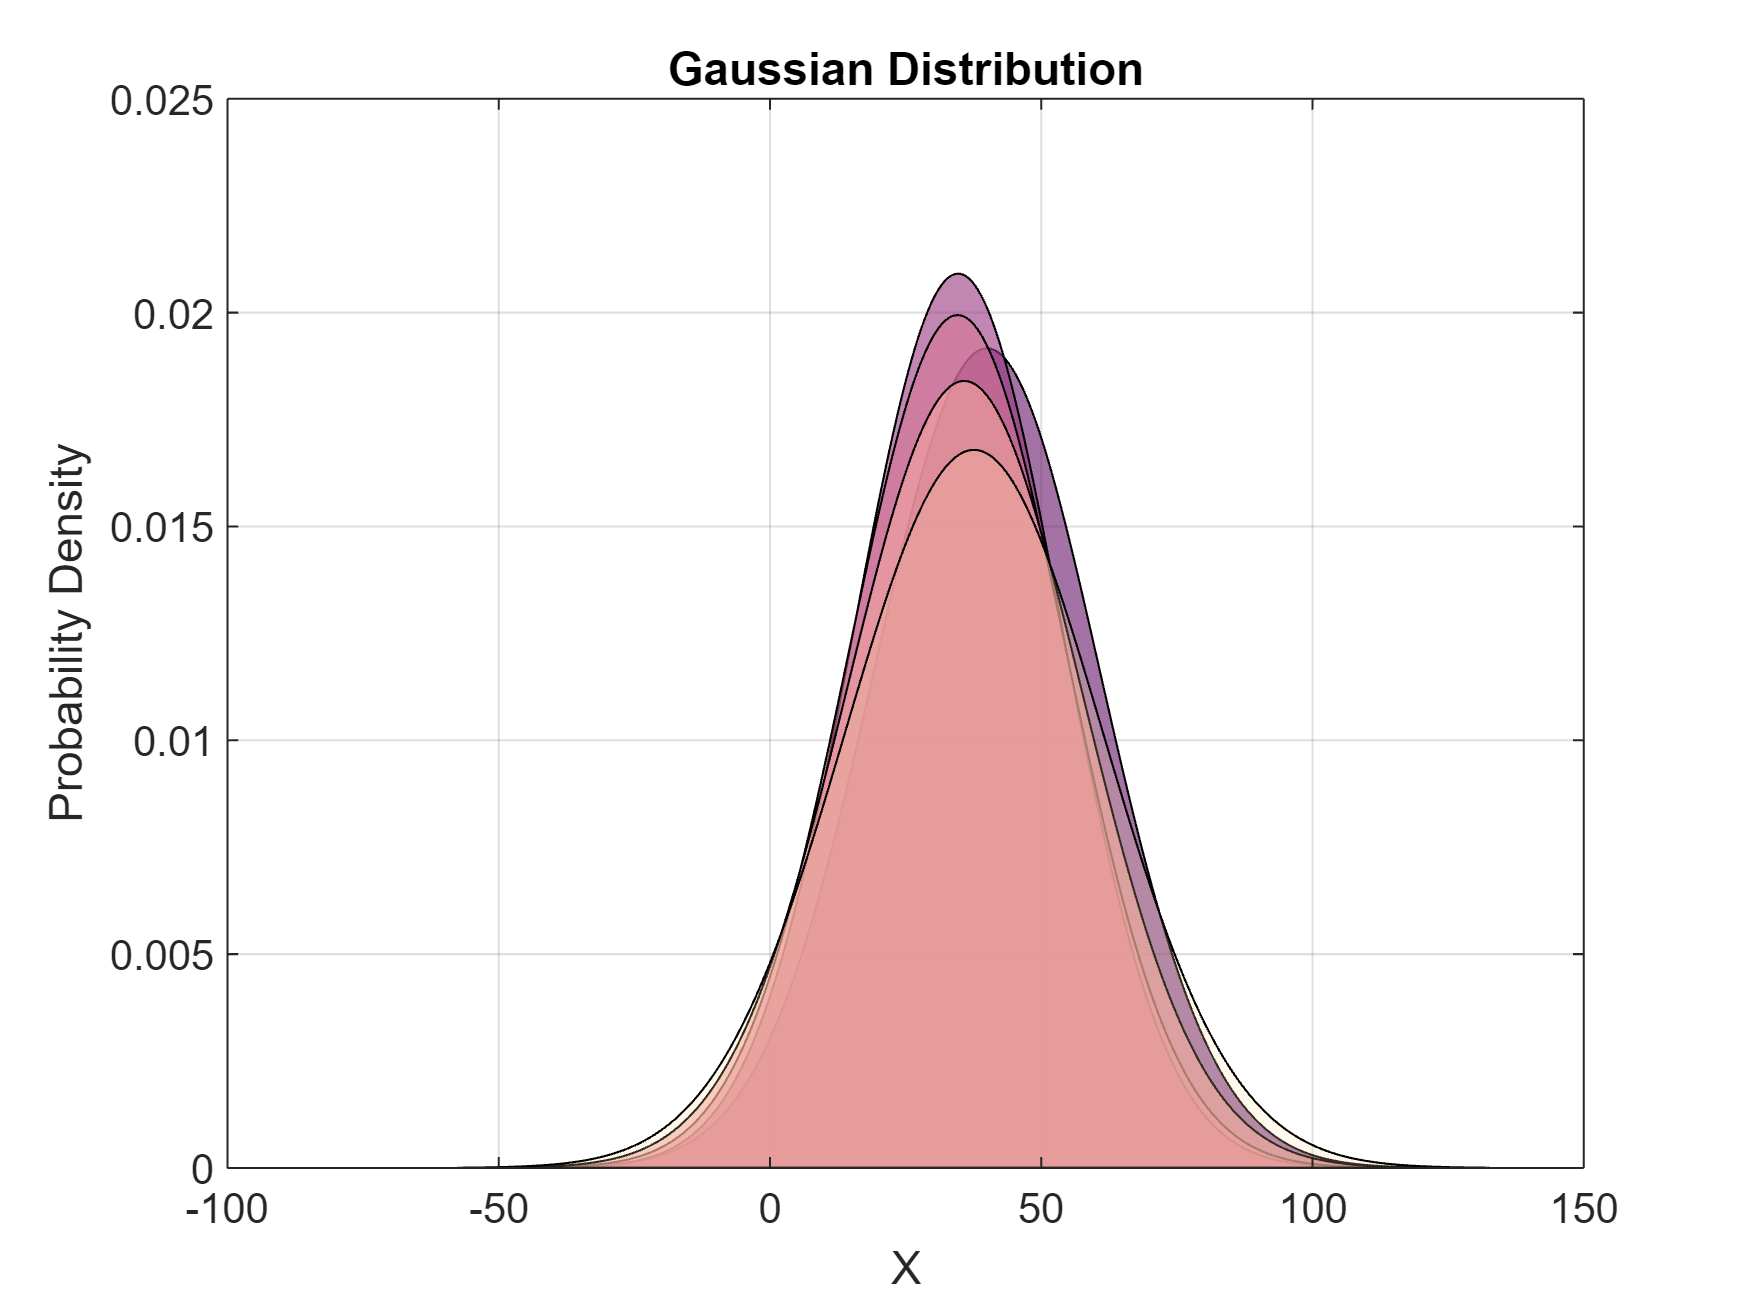

for i=1:5
    mu = mu_v(i);
    sigma = std_v(i);
x = linspace(mu - 4*sigma, mu + 4*sigma, 1000);
% Compute the probability density function (PDF) of the normal distribution
pdf_normal = normpdf(x, mu, sigma);

% Plot the Gaussian distribution as a filled plot wit transparency
fill(x, pdf_normal,rgb_hep(i,:), 'FaceAlpha', alphas(i));
hold on;

% Plot the PDF curve for reference
%plot(x, pdf_normal, 'b', 'LineWidth', 2);
xlabel('X');
ylabel('Probability Density');
title('Gaussian Distribution');
grid on;

end